% Training set
trainFD001 = readmatrix('train_FD001.txt');
trainFD002 = readmatrix('train_FD002.txt');
trainFD003 = readmatrix('train_FD003.txt');
trainFD004 = readmatrix('train_FD004.txt');

% Test set
testFD001 = readmatrix('test_FD001.txt');
testFD002 = readmatrix('test_FD002.txt');
testFD003 = readmatrix('test_FD003.txt');
testFD004 = readmatrix('test_FD004.txt');

% RUL (Remaining Useful Life)
RUL_FD001 = readmatrix('RUL_FD001.txt');
RUL_FD002 = readmatrix('RUL_FD002.txt');
RUL_FD003 = readmatrix('RUL_FD003.txt');
RUL_FD004 = readmatrix('RUL_FD004.txt');

% import dataset
trainFD001 = readmatrix('train_FD001.txt');

% extract predictors and variables
[X_train, unit_train, cycle_train] = extractPredictors(trainFD001);

Matrice X: 20631 osservazioni (righe) × 24 variabili (colonne)



% visualize first 5 observation
disp('first five observation of matrix X_train:');

Prime 5 osservazioni della matrice X_train:



disp(X_train(1:5,:));

   1.0e+03 *

   -0.0000   -0.0000    0.1000    0.5187    0.6418    1.5897    1.4006    0.0146    0.0216    0.5544    2.3881    9.0462    0.0013    0.0475    0.5217    2.3880    8.1386    0.0084    0.0000    0.3920    2.3880    0.1000    0.0391    0.0234
    0.0000   -0.0000    0.1000    0.5187    0.6421    1.5918    1.4031    0.0146    0.0216    0.5537    2.3880    9.0441    0.0013    0.0475    0.5223    2.3881    8.1315    0.0084    0.0000    0.3920    2.3880    0.1000    0.0390    0.0234
   -0.0000    0.0000    0.1000    0.5187    0.6423    1.5880    1.4042    0.0146    0.0216    0.5543    2.3881    9.0529    0.0013    0.0473    0.5224    2.3880    8.1332    0.0084    0.0000    0.3900    2.3880    0.1000    0.0390    0.0233
    0.0000         0    0.1000    0.5187    0.6423    1.5828    1.4019    0.0146    0.0216    0.5544    2.3881    9.0495    0.0013    0.0471    0.5229    2.3881    8.1338    0.0084    0.0000    0.3920    2.3880    0.1000    0.0389    0.0234
   -0.0000   -0.0000  

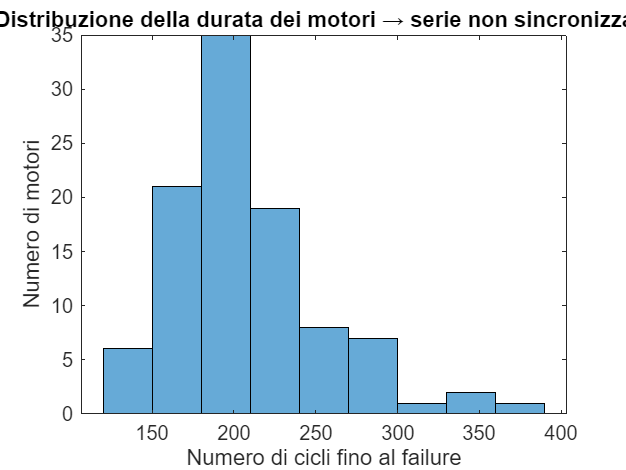



% ---- 1. check non syncronize temporal series ----
uniqueUnits = unique(unit_train);
nUnits = numel(uniqueUnits);
cyclesPerUnit = zeros(nUnits,1);

for i = 1:nUnits
    cyclesPerUnit(i) = sum(unit_train==uniqueUnits(i));
end

figure;
histogram(cyclesPerUnit);
xlabel('number of cycle until failure');
ylabel('number of enginees');
title('distribution of engine life → non syncronize serie');


fprintf('number of engine: %d\n', nUnits);

Numero motori: 100


fprintf('average engine life (cycles): %.2f\n', mean(cyclesPerUnit));

Durata media dei motori (cicli): 206.31



% ---- 2. check missing values ----
nMissing = sum(isnan(X_train),1);
missingVars = find(nMissing>0);

if ~isempty(missingVars)
    fprintf('variables with missed values:\n');
    disp(missingVars);
else
    fprintf('No missing values.\n');
end

Nessun valore mancante rilevato.



% ---- 3.constant variables----
varPerCol = var(X_train);
constVars = find(varPerCol==0);

if ~isempty(constVars)
    fprintf('constant variables:\n');
    disp(constVars);
else
    fprintf('no constant variable.\n');
end

Variabili costanti (nessuna informazione utile):


     3    21    22



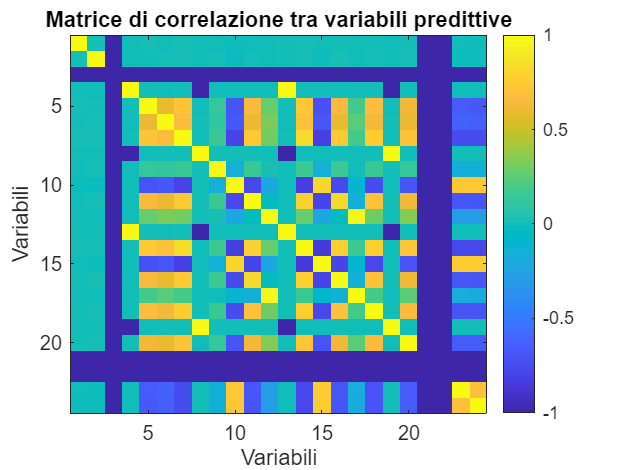


% ---- 4.correlation ----
corrMatrix = corr(X_train);
figure;
imagesc(corrMatrix);
colorbar;
title('correlation matrix between variables');
xlabel('variables');
ylabel('variables');

 Analisi dataset: train_FD001.txt


Matrice X: 20631 osservazioni (righe) × 24 variabili (colonne)


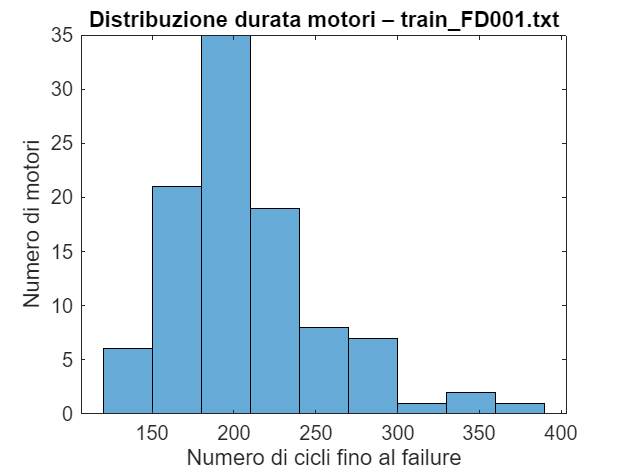

Numero motori: 100


Durata media dei motori (cicli): 206.31


Nessun valore mancante rilevato.


Variabili costanti:


     3    21    22



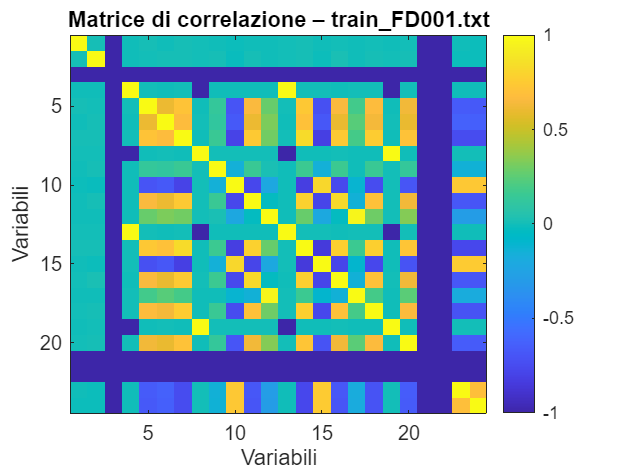

 Analisi dataset: train_FD002.txt


Matrice X: 53759 osservazioni (righe) × 24 variabili (colonne)


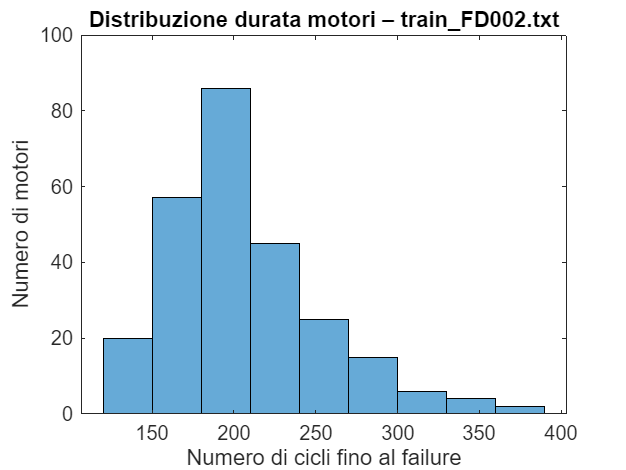

Numero motori: 260


Durata media dei motori (cicli): 206.77


Nessun valore mancante rilevato.


Nessuna variabile costante trovata.


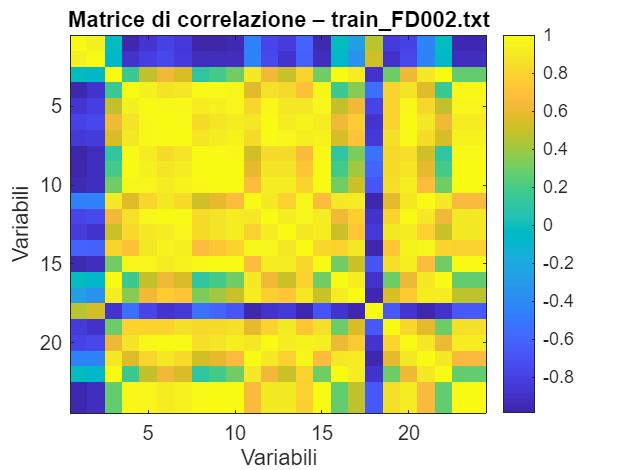

 Analisi dataset: train_FD003.txt


Matrice X: 24720 osservazioni (righe) × 24 variabili (colonne)


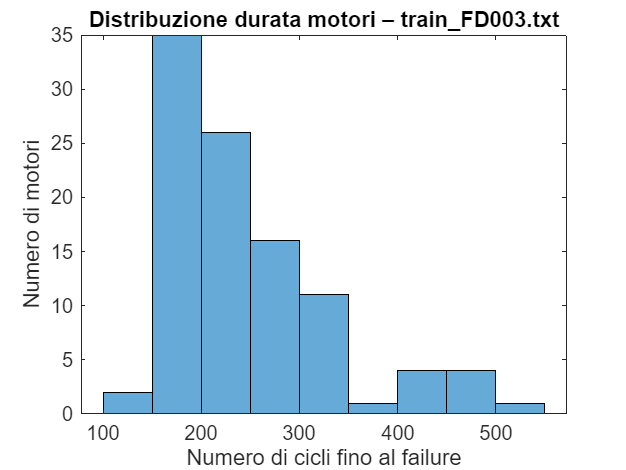

Numero motori: 100


Durata media dei motori (cicli): 247.20


Nessun valore mancante rilevato.


Variabili costanti:


     3    21    22



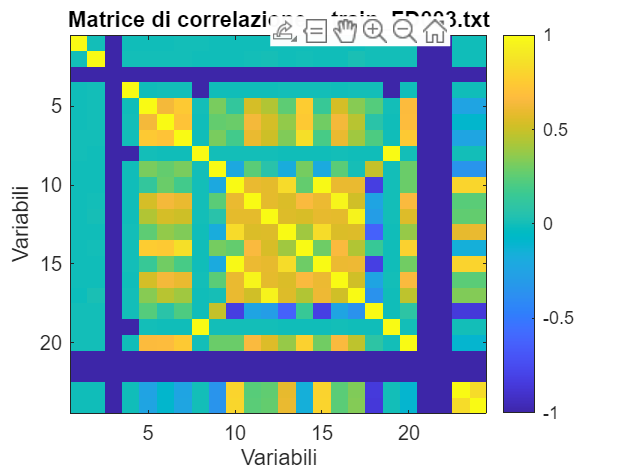

 Analisi dataset: train_FD004.txt


Matrice X: 61249 osservazioni (righe) × 24 variabili (colonne)


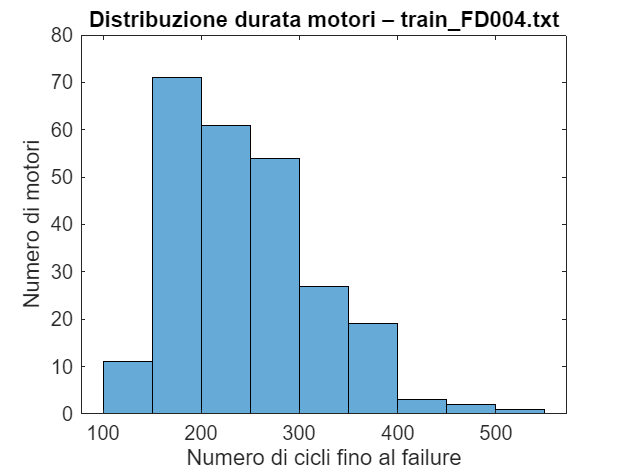

Numero motori: 249


Durata media dei motori (cicli): 245.98


Nessun valore mancante rilevato.


Nessuna variabile costante trovata.


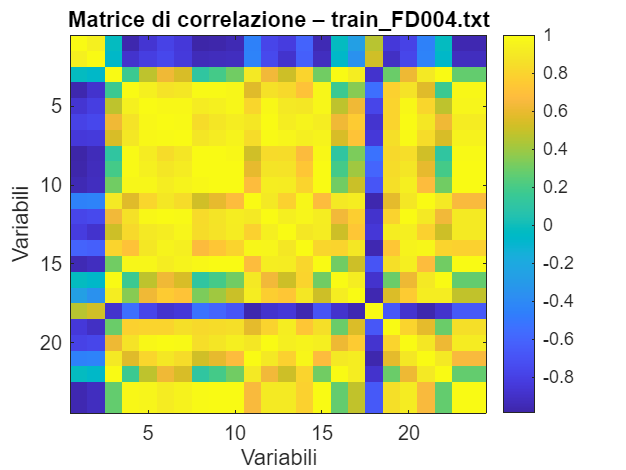

trainFiles = { ...
    'train_FD001.txt', ...
    'train_FD002.txt', ...
    'train_FD003.txt', ...
    'train_FD004.txt'};

% Loop on every dataset
for f = 1:numel(trainFiles)
    fprintf('\n==============================\n');
    fprintf(' Analysis dataset: %s\n', trainFiles{f});
    fprintf('==============================\n');
    
    trainData = readmatrix(trainFiles{f});
    
    [X_train, unit_train, cycle_train] = extractPredictors(trainData);
    
    uniqueUnits = unique(unit_train);
    nUnits = numel(uniqueUnits);
    cyclesPerUnit = zeros(nUnits,1);

    for i = 1:nUnits
        cyclesPerUnit(i) = sum(unit_train==uniqueUnits(i));
    end

    figure;
    histogram(cyclesPerUnit);
    xlabel('number of cycles untill failure');
    ylabel('Number of engines');
    title(sprintf('distribution engine life – %s', trainFiles{f}), 'Interpreter','none');

    fprintf('number of eninges: %d\n', nUnits);
    fprintf('average engine life (cycles): %.2f\n', mean(cyclesPerUnit));

    nMissing = sum(isnan(X_train),1);
    missingVars = find(nMissing>0);

    if ~isempty(missingVars)
        fprintf('Variables with missing values:\n');
        disp(missingVars);
    else
        fprintf('no missin values.\n');
    end

    varPerCol = var(X_train);
    constVars = find(varPerCol==0);

    if ~isempty(constVars)
        fprintf('constant variables:\n');
        disp(constVars);
    else
        fprintf('no constant variables.\n');
    end

    corrMatrix = corr(X_train);
    figure;
    imagesc(corrMatrix);
    colorbar;
    title(sprintf('correlation matrixe – %s', trainFiles{f}), 'Interpreter','none');
    xlabel('variables');
    ylabel('variables');
end

 Analisi dataset: train_FD001.txt


Matrice X: 20631 osservazioni (righe) × 24 variabili (colonne)


Il dataset ha 20631 osservazioni (righe) e 24 variabili predittive (colonne).


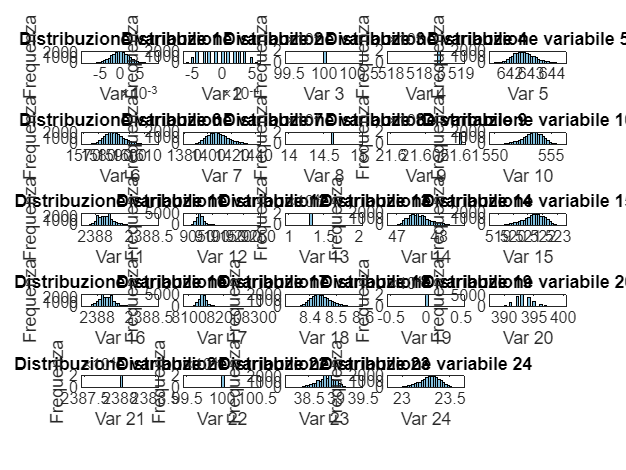

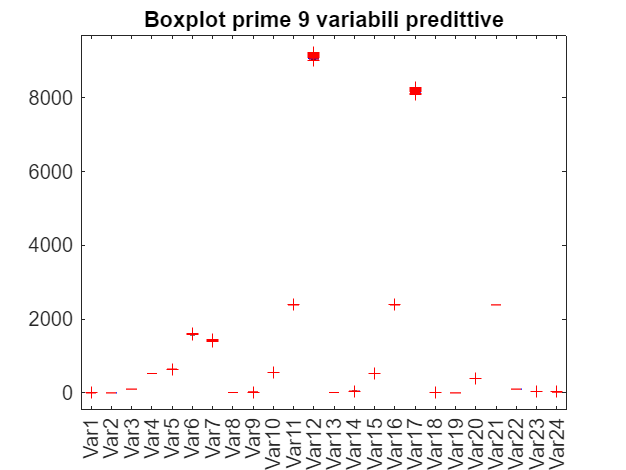

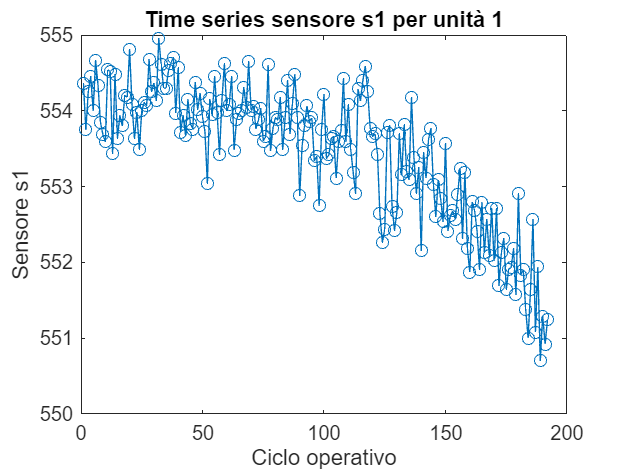

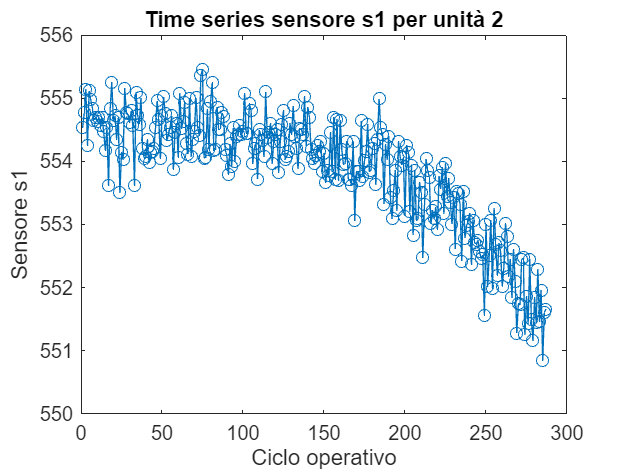

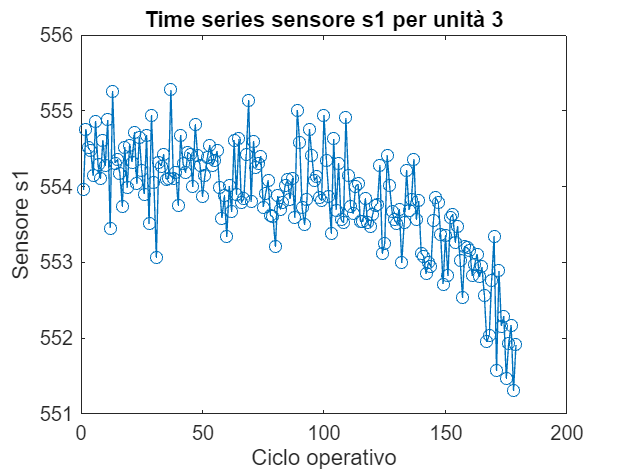

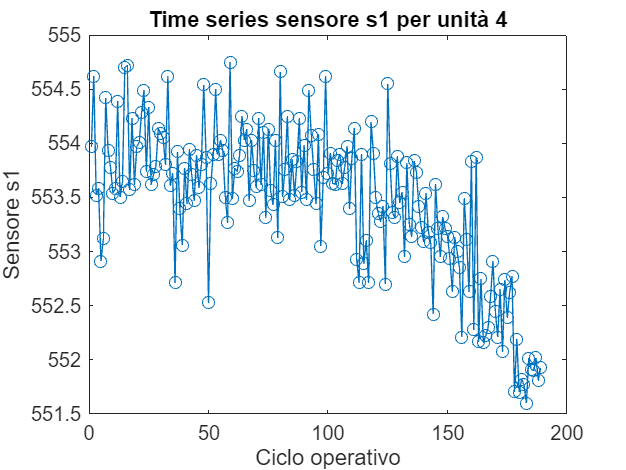

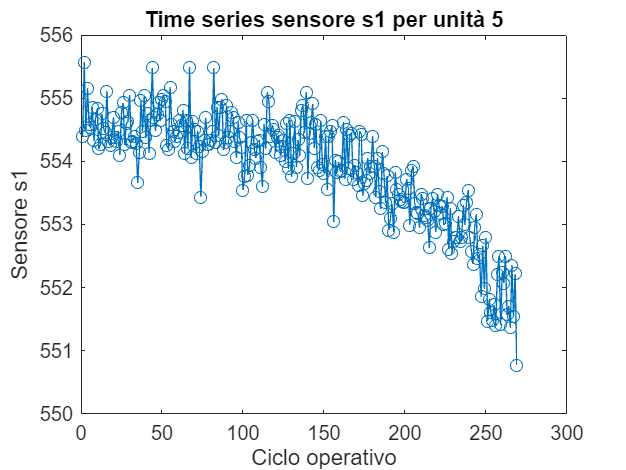

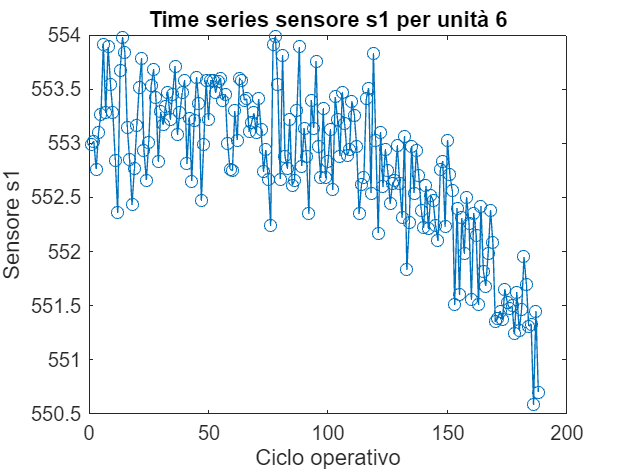

 Analisi dataset: train_FD002.txt


Matrice X: 53759 osservazioni (righe) × 24 variabili (colonne)


Il dataset ha 53759 osservazioni (righe) e 24 variabili predittive (colonne).


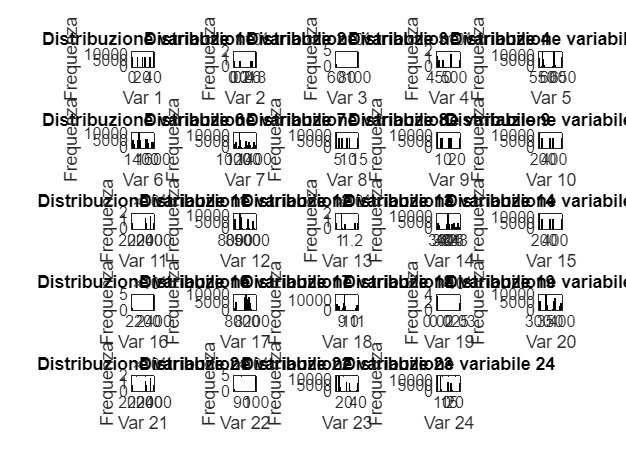

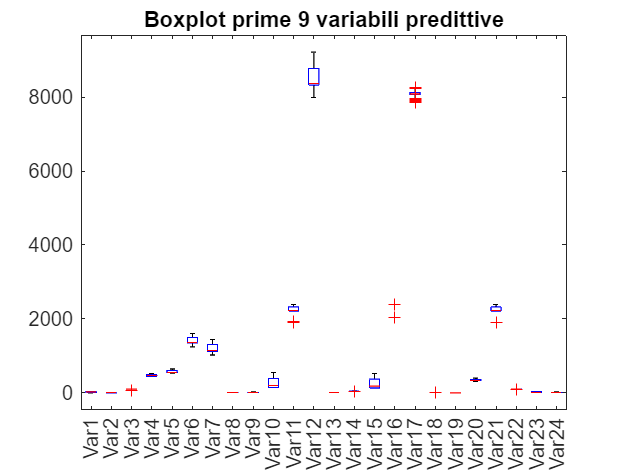

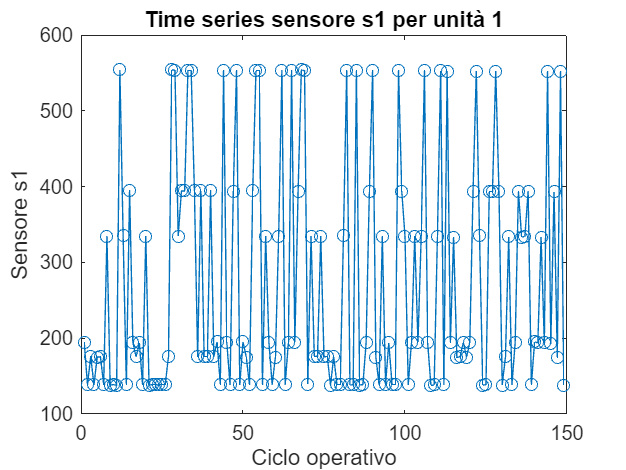

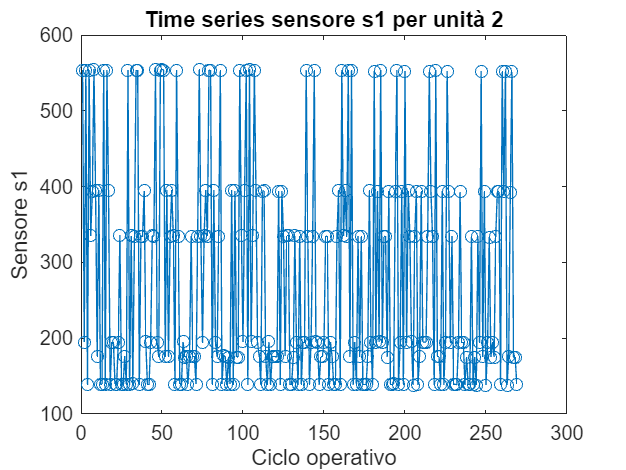

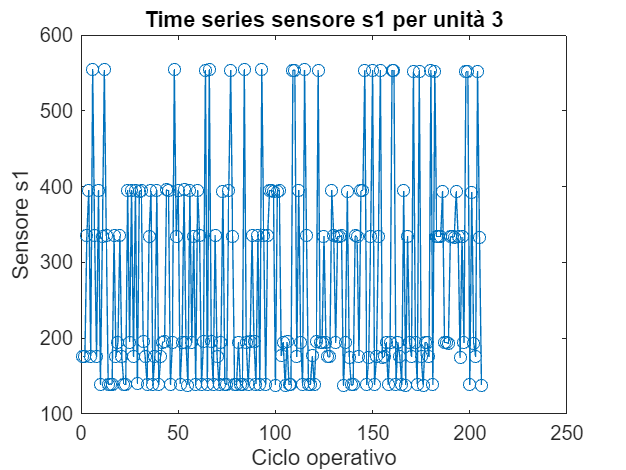

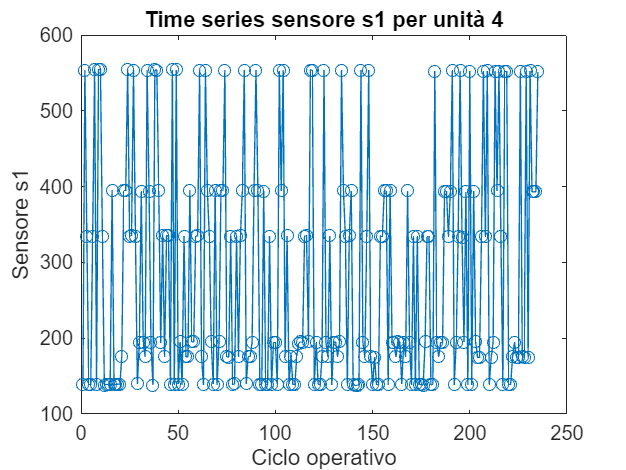

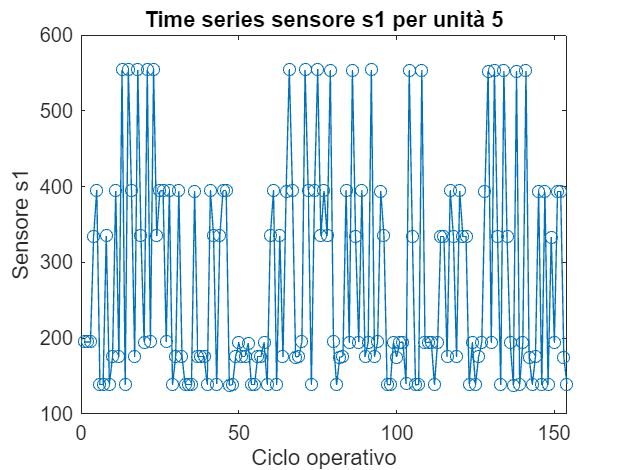

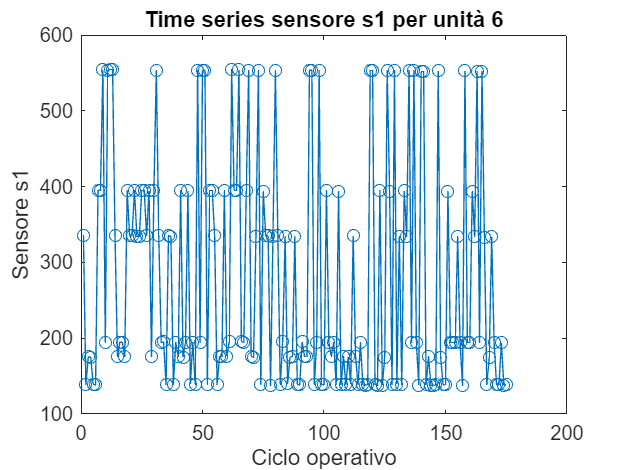

 Analisi dataset: train_FD003.txt


Matrice X: 24720 osservazioni (righe) × 24 variabili (colonne)


Il dataset ha 24720 osservazioni (righe) e 24 variabili predittive (colonne).


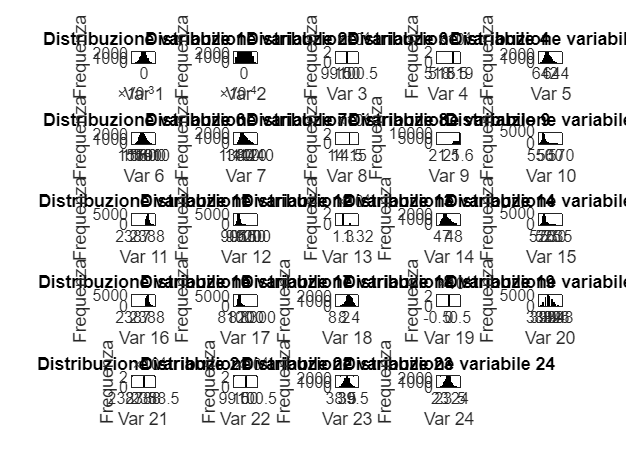

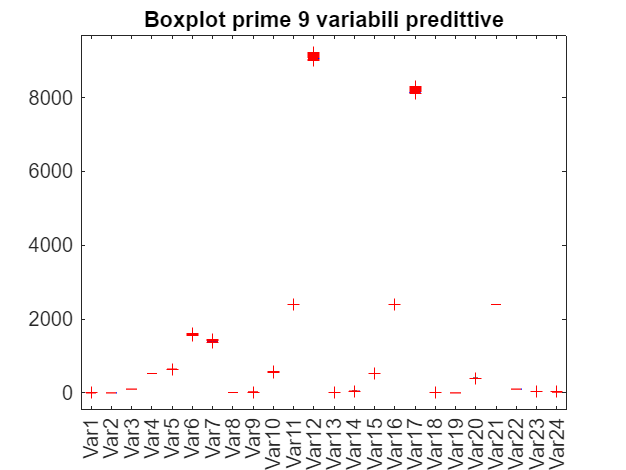

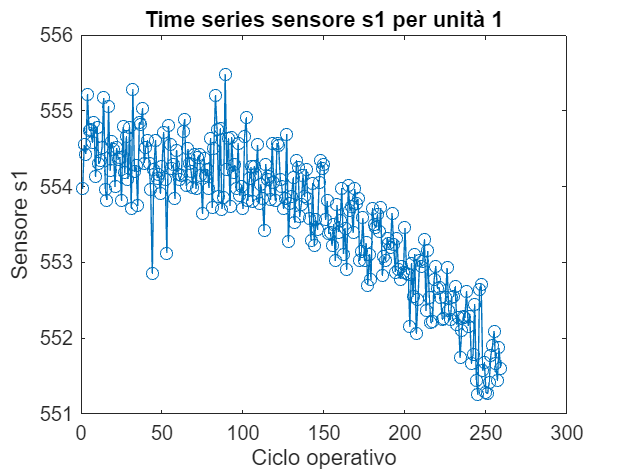

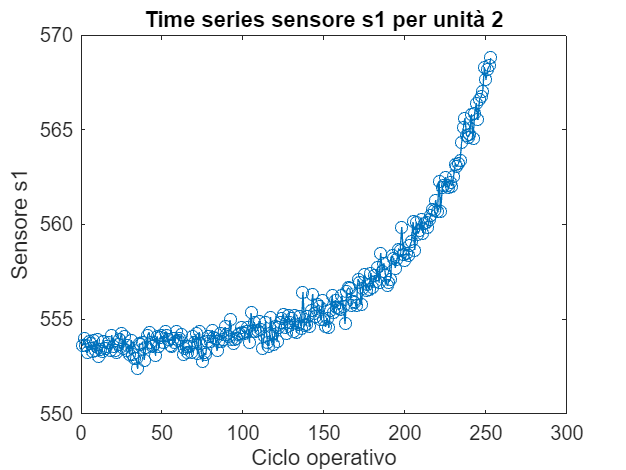

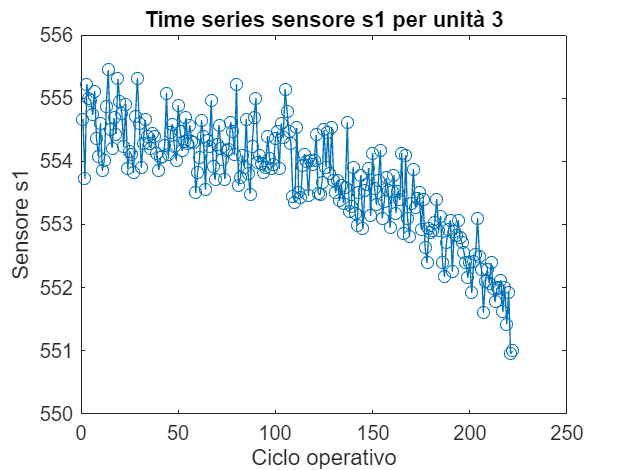

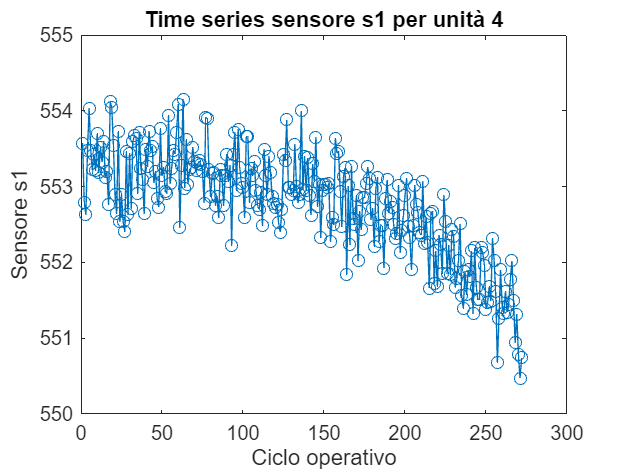

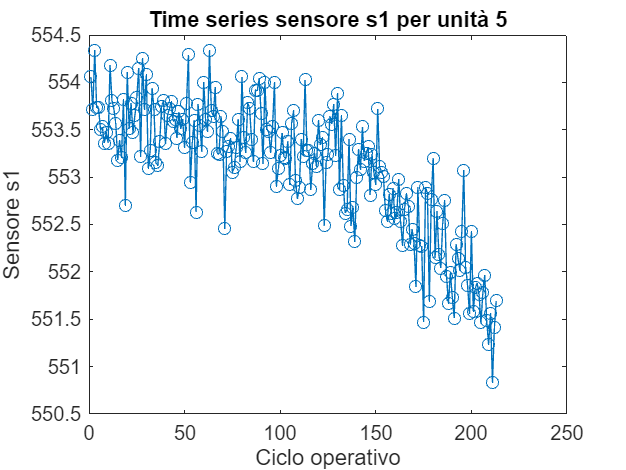

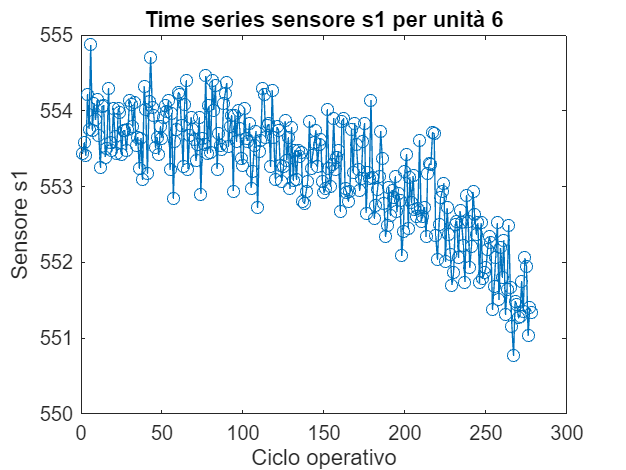

 Analisi dataset: train_FD004.txt


Matrice X: 61249 osservazioni (righe) × 24 variabili (colonne)


Il dataset ha 61249 osservazioni (righe) e 24 variabili predittive (colonne).


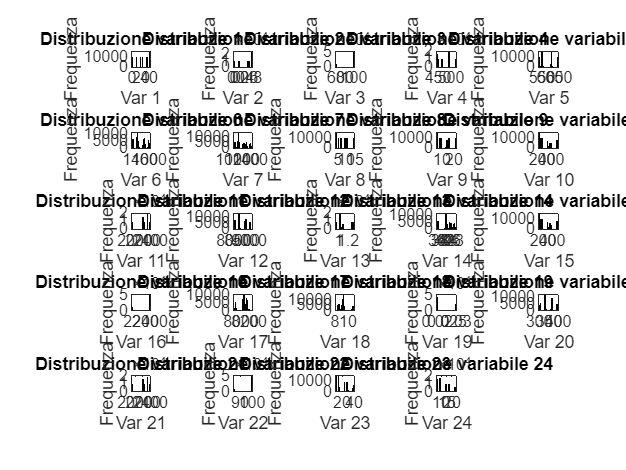

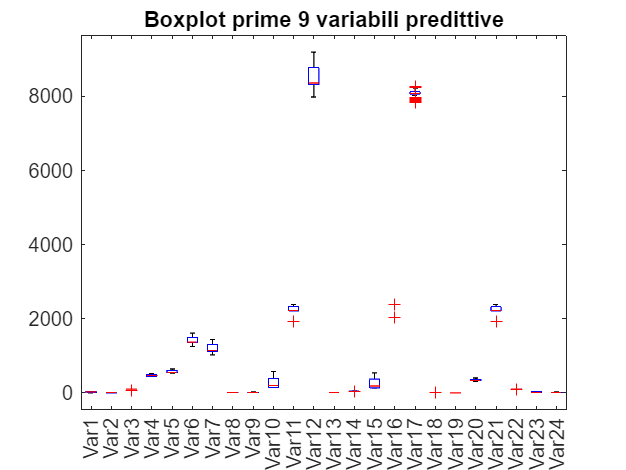

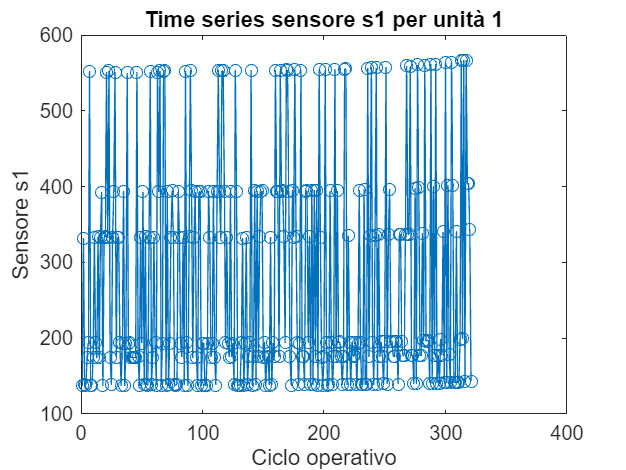

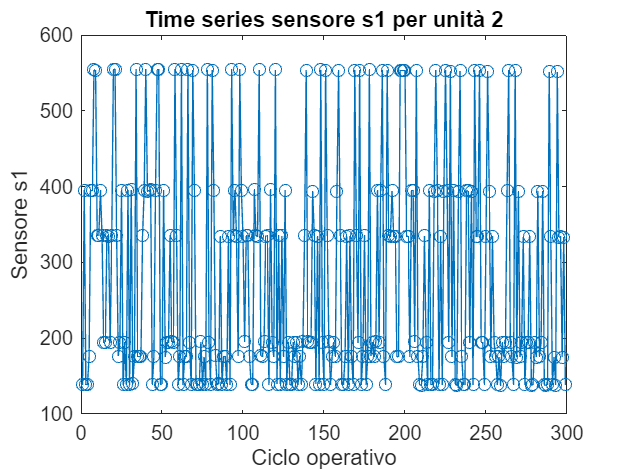

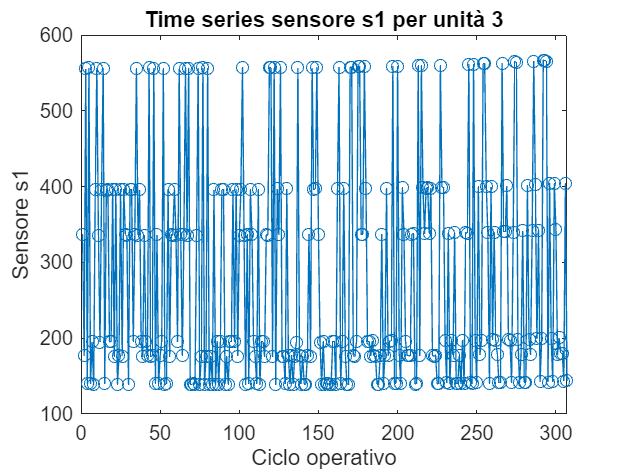

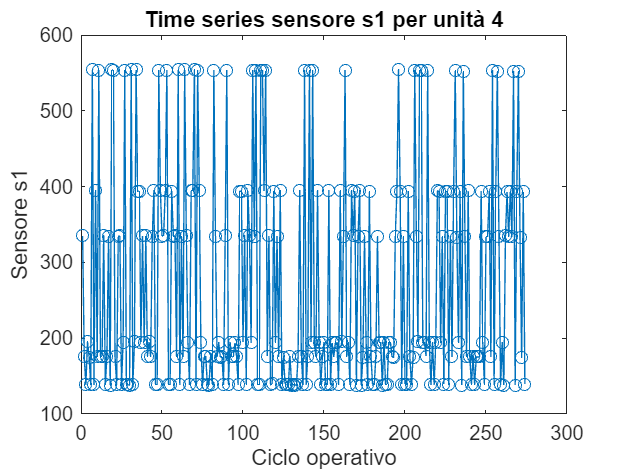

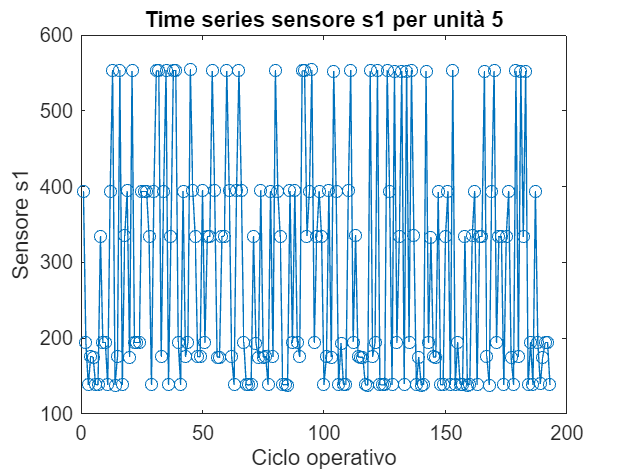

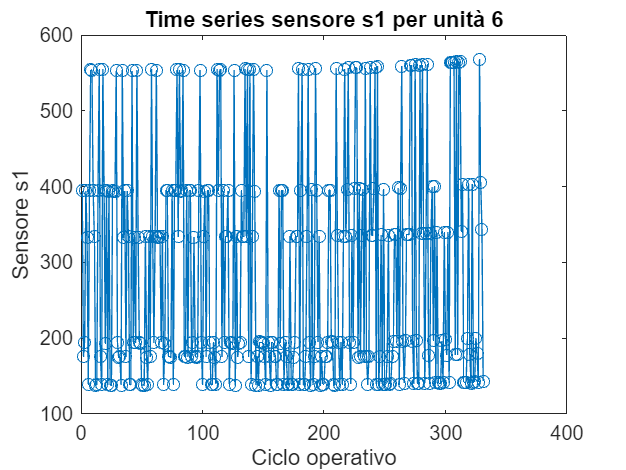

trainFiles = { ...
    'train_FD001.txt', ...
    'train_FD002.txt', ...
    'train_FD003.txt', ...
    'train_FD004.txt'};

for f = 1:numel(trainFiles)
    fprintf('\n==============================\n');
    fprintf(' Analysis dataset: %s\n', trainFiles{f});
    fprintf('==============================\n');
    
    trainData = readmatrix(trainFiles{f});
    
    [X, unit_train, cycle_train] = extractPredictors(trainData);


%% 1. Number of observation and variables
[nObs, nVar] = size(X);
fprintf(' dataset has %d observations (row) e %d predictive variables (column).\n', nObs, nVar);

%% 2. histograms 
figure;
for i = 1:min(24,nVar)  % 
    subplot(5,5,i);
    histogram(X(:,i),30,'FaceColor',[0.2 0.6 0.8],'EdgeColor','k');
    xlabel(sprintf('Var %d', i));
    ylabel('frequences');
    title(sprintf('variable distribution %d', i));
end

%% 3. Boxplot for outliers
figure;
boxplot(X(:,1:24),'Labels',arrayfun(@(x) sprintf('Var%d',x),1:24,'UniformOutput',false));
title('Boxplot');

%% 4. Visualize temposal series of engine
% for example unit 1
for unitID = 1:10
idx = (unit_train == unitID);
figure;
plot(cycle_train(idx), X(idx,10), '-o'); % for example sensor 5
xlabel('operative cycle');
ylabel('Sensor s5');
title(sprintf('Time series sensor s5 unit %d', unitID));
end
end